# Signal Processing Lab

**Group Member:**

Name/ID

1.

2.

3.

**References:** 

1) Matlab Signal Processing MathWorks

2) M. West, et. al., "Periodically Triggered Seismicity at Mount Wrangell, Alaska, After the Sumatra Earthquake" Science 2005. (https://science.sciencemag.org/content/308/5725/1144.abstract)

## Generating Signals

Let's start by trying to create simple a sine wave. Suppose we use a sampling frequency $f_s$ = 100 Hz to sample a continous sine wave signal. This is equivalent to saying that for every 1 sec, we will take 100 samples, or equivalently, the time interval between each sample is $\frac{1}{f_s }=$ $\frac{1}{100}s$ apart (i.e. 0.01 s)

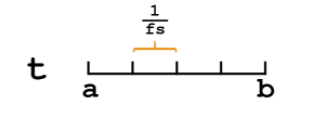

You can create time steps from a to b with a colon operator:

`    a:1/fs:b`

**TASK**

Specify a sample rate of `100` Hz in a variable named `fs`.

Then create a signal named `t` that extends from  `0` to `1`, with time steps that are `1``/``fs`.

To create a simple sine wave, we can use a sin function command:

`    s` `=` `sin``(``2``*``pi``*``f``*``t``)`

, where `f` is the frequency, and `t` are the time steps.

**TASK**

Create a sine signal named `sig` at the sample times in `t`. Use a frequency of `5 Hz`. 

Then create a plot of `sig` versus `t`.

*Voila*! You should get a nice looking sine wave in the output window. But in reality, most signal occuring naturally does not look as nice as this due to other interferences from other signal, which we often calls it as *noise*. To model this noise, we can simulate it using a rand function that generates random number which has the same size as our original signal so we can add to it:

`    randn(size(``s``))`

**TASK**

Create a vector of random numbers named `noise` that is the same size as `sig`. Multiply the vector by `0.1` to scale the vector. Add the signal vector with the noise vector. Name the output `sigNoisy`. Then create a plot of `sigNoisy` versus `t`.

Now, our signal looks more like data you would obtain in the real world with all the imperfections. 

## Earthquake Signal

In this lab, we will take a closer look at the seismic activity that was caused by an earthquake in Sumatra on Dec 26, 2004. The surface wave from the earthquake was so strong that it was detectable all the way in Alaska, US. Three seismic stations, namely, HAARP, Paxson, and Wrangell North Crator station located in Alaska were able to detect this signal. In fact, the energy wave was powerful enough that it subsequently triggerred smaller earthquakes near one of the seismic stations.  

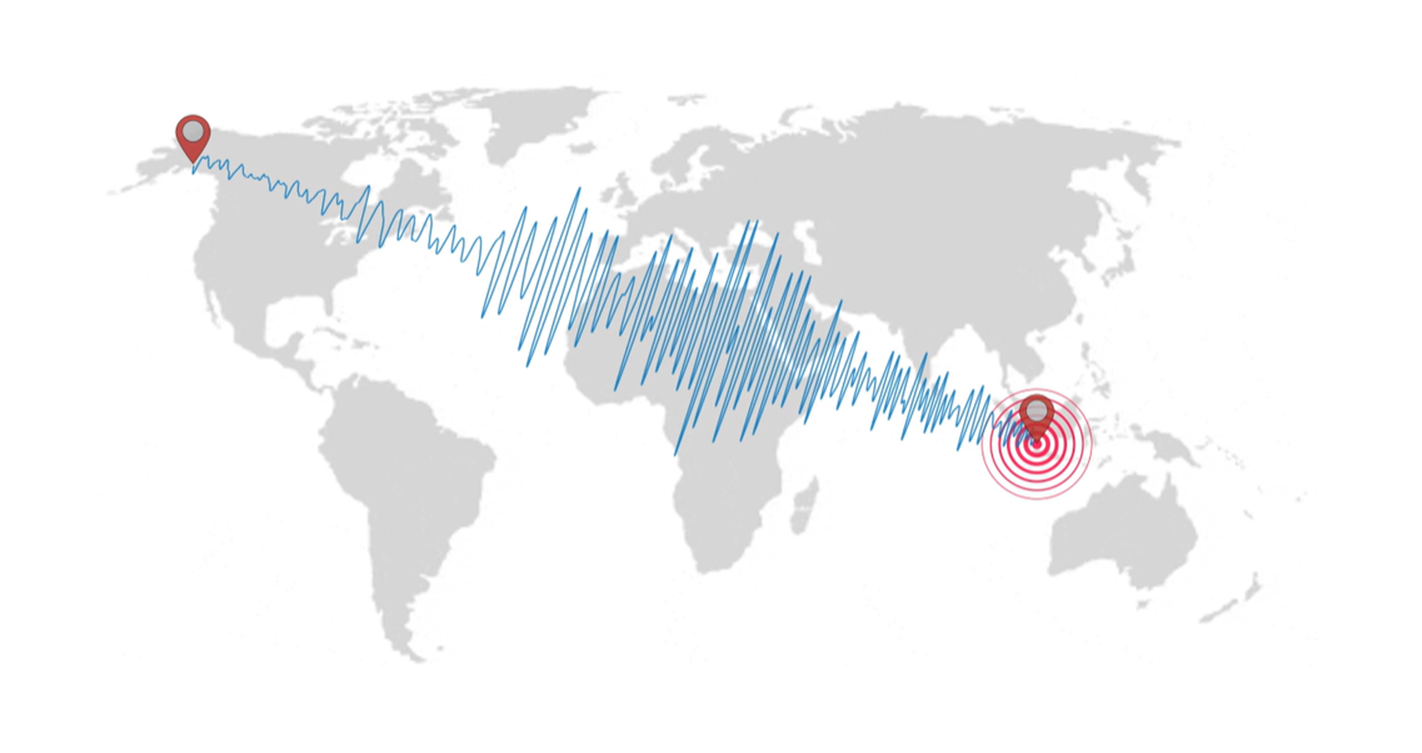

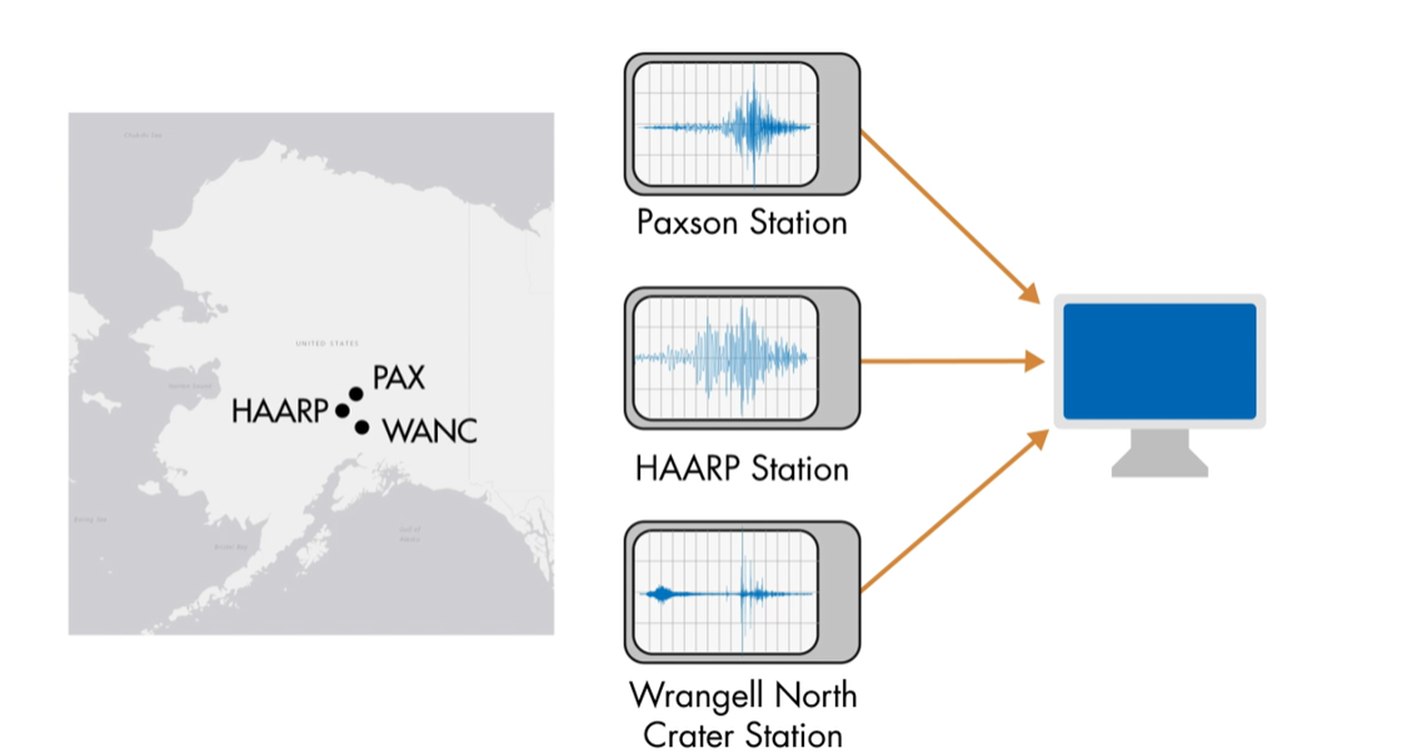

To  make sense out of these data, we will use some of the techniques we have learned in class to help us analyze the signal. We will first import the raw signal recorded by these seismic stations. We will then need to preprocess the signal to get it into the form that is easier to analyze. Next, we will analyze its spectrum to find out more information about its frequency content. And lastly, we might apply some filtering to our signal in order to highlight the signal content that we want to closely examined while suppressing other signals not relevant to our analysis. 

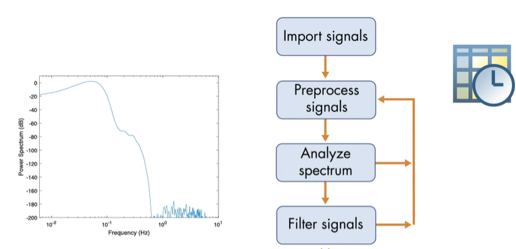

## Import Raw data

There are 4 raw files that we will use for this lab. They are:

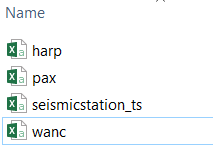

The time series sesimic readings  from HAARP, Paxson, and Wrangell North Crater Station are saved in harp.csv, pax.csv and wanc .csv, respectively.  'Seismicstation_ts.csv' contains the time step used in each of the station. 

**TASK**

Import the time steps stored in `"seismicstation_ts.csv"` to an array named `Ts`. You can use the function `readmatrix("YouFileNameHere.csv") `to import data from a csv file into a *numeric array. *Save this to a variable named `Ts . `The variable Ts will contain time steps for three seismometers located at stations HARP, PAX, and WANC (in that particular order). Your variable Ts should have the size of 1 x 3.  

Assign the **first element **of Ts to a variable named `harpTs`

Now we will proceed with importing the seismic readings. We will need to create a time series data for it, where each sample has an associated time. The raw signal only contains amplitude of the seismic wave with no information on the time step of each data point. However, we can easily figure that out since we know the sampling frequency that the seismometer at each of the station was using. One easy way to create a time series is to use a function called `readtimetable. The syntax is:`

`    myTimeTable = readtimetable("myrawdata.csv","SampleRate",Fs)`

`Note how "SampleRate" option is used to associate the time to each sample by providing the sampling rate Fs.`

**TASK**

Import the seismic signal stored in `"harp.csv"` to a timetable named `harp`. Specify the *sample rate* using information from the varible harpTs.

We can plot this time table using a plot command:

`    plot(x,y) `

`The equivalent variable x and y for our timetable is Time and Signal, respectively. We can access them using a dot notation:`

`    myTimeTable.MyVariableNameInTheColumnTitle`

Plot `harp.Signal` versus `harp.Time with Time on the x-axis and Signal on the y-axis`

## Preprocessing Signals

Before performing spectral analysis on your signals, you should probably do some basic preprocessing. Initial preprocessing can include:

- Normalizing

- Resampling

- Aligning

You'll perform these preprocessing steps in the next section. 

But first, let's tidy up our data a bit by specifying only the range of the data points that we are interested in. We can start by specifying the start and the endpoint of the event. We will specify our endpoints to be in unit of seconds to align with our default unit for Time in our timetable. The function `seconds` can be used for this purpose:

    `nsec`` = seconds(``n``)`

**TASK**

Create variables `tstart` and `tend` that contain 2000 and 4000 seconds, respectively. Note you will call `seconds` function twice, one for creating `tstart` and one for `tend`

Now that you have the end points define, you need to specify a range with `timerange` function:

    `lim = timerange(t1,t2)`

**TASK**

Create a `timerange` variable that specifies a range from `tstart` to `tend`. Name the output variable `timeLimits`.

In a timetable, each row is associated with a time. To get all the data within a time range, use the colon operator:

`    tbl` `=` `tbl``(``lim``,:``)`

**TASK**

Extract the region of the HARP signal within `timeLimits`. Reassign the output back to `harp`. Then replot the processed HARP signal

Compared to the original plot of harp signal, your x-axis should only show a value that runs from 2000 to 4000 sec. Note that the above operation will overide the variable harp in its original form. If you need to redo the above step, you will need to reimport the original data from CSV file into the variable.

## Power Spectrum Analysis

To view the frequency content of a signal, you can calculate the power spectrum with the `pspectrum` function.

`    pspectrum``(``mysig``)`

**TASK**

Plot the power spectrum of the `harp` signal. 

There are no significant peaks in the power spectrum. The frequency range of these seismic surface waves is small, so you need to zoom in on the plot.

To zoom in on the meaningful seismic activity, you can set the frequency limits while calculating the power spectrum.

`    pspectrum``(``mysig``,``"FrequencyLimits"``,``[``a` `b``])`

**TASK**

Re-plot the power spectrum of the `harp` signal, but this time set the frequency limit to be from 0 to 1Hz instead

## Comparing Signals

Now that we have learned how to perform some basic preprocessing and data analysis on a signal, let's start our analysis by considering all three of the signal collected at the stations

**TASK**

Create a time serie data for harp, pax and ,wanc using the corresponding sampling rate from the seismicstation_ts.csv file. (Please re-import harp data here as well since we want to look at all the data point this time, not just at a specific range we did previously). Be sure to use the correct value for sampling rate in the correct order according to the seismicstation_ts.csv file

We can visualize the output from the 3 stations by using a tiled layouts. To start creating a tiled layout, define the number of plots in the layout:

`  tiledlayout``(``2``,``3``)`

This code creates a layout with 2 rows and 3 columns. To start filling in the tiled layout, use the `nexttile` function.

    `tiledlayout``(``2``,``3``)`

    `nexttile`

    `plot``(``x1,``y1)`

    `nexttile`

    `plot``(``x2``,``y2``)`

You can also create a title for each plot by inserting `title("YourPlotName") `right after the `plot` command:

  `plot(x1,y1)`

` title("YourPlotName")`

**TASK**

Create a tiled layout with `3` rows and `1` column. Then, start filling in the tile with harp, pax, and wanc signal. Use the title HARP, PAX, and WANC, respectively.

Based on the time series plot that you get. Please describe in words the similarities or differences that you observe among the signal. Does one of the signals stand out from the rest? How so? 

*Enter your response below:*

__________________________________________________________

For now, let's compare the frequency content of the HARP and PAX signals. Since these signals have the same sample rate (i.e. $\frac{1}{0\ldotp 02}$ Hz), you can combine these timetables with the `synchronize` function.

`    t = synchronize(t1,t2)`

**TASK**

Combine `harp` and `pax` into one table named `quakes`. Use `harp` as the first input and `pax` as the second input. 

Your resulting time table should look something like this:

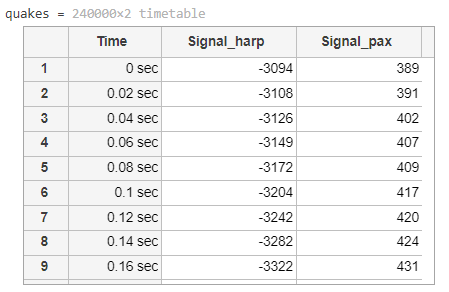

Let's calculate the powerspectrum for both signals from the `quakes` timetable. 

Calculate the power spectrum of the `quakes` timetable. Zoom in on the low frequencies by setting the frequency limits to `[0 1]`. Be sure to type in `figure `before you call any plotting commands because right now MATLAB still considers the 3rd plot in the previous tiledplot as the "active plot". Any new plot command would just overwrite the original plot. 

The frequency response you get from HARP and PAX signal should look quite similar in terms of the general shape, with some diferrences in the amplitude. 

Now let's try to combine all three signals into one timetable. 

Since WANC signal has different frequency compared to HARP and PAX, describe how does your timetable look when MATLAB try to  merge all three data into one timetable? 

*Enter your response below:*

_______________________________________________________

From your observation above, it looks like having different time interval in the sampling interval of the 3 signals can be problematic when we try to analyze them together.  To overcome this issue, we can make the time interval between samples to be the same across. We can either 'upsample' (increase the sampling rate) or 'downsample' (decrease the sampling rate) of our signals. We noted that the sampling frequency from Mount Wrangell is twice as fast as the other signals and hence the time interval is smaller. Let's try to downsample the WANC signal to match the sampling rate of the other two signals. The commnand to use is `resample`:

    `  y = resample(x,``p``,``q``)`

`    ,where x is your original signal, p and q are integer resample factors. The output y will have p/q samples from x`

For example,

`    y` `=` `resample``(``x``,``2``,``3``)`

resamples `x` to `2``/``3` times the original sample rate.

**TASK**

The time step vector `Ts` is displayed in the script. Notice that the third element, corresponding to the Mount Wrangell signal, has a smaller time step, and hence, the sampling rate is twice as fast.

Resample `wanc.Signal` to match the sample rate for `harp` and `pax (`i.e. you want the sampling rate of wanc to be half that of the original wanc signal). Name the output signal `downwanc`

This should output an array with amplitude data that we need to merge with the time vector to form a time series data. Since we know that the time signal should be the same as HARP and PAX since we just resampled WANC to match, you can use the time vector from either one. 

You can use the `timetable` function to make a timetable from vectors already in your workspace.

`tbl` `=` `timetable``(``time``,``data``,` `...`

    `'VariableNames'``,``"Signal"``)`

Set the `'VariableNames'` option so that you can standardize your table variable names.

**TASK**

Replace `wanc` with a new timetable. Use `harp.Time` as the time vector and `downwanc` as the data. Set the variable name to `"Signal"`.

Another trend you should have observed is that the magnitude of the WANC signal is much smaller when compared to the other two signals. (Go back to your tiled plot and look at the scale on the y-axis). For our particular analysis, we won't care too much about the absolute maginitude of each signal, so it will be easier to compare signals if their magnitude are normalized to a similar range. 

The `normalize` function can normalize timetables.

`    tbl` `=` `normalize``(``tbl``)`

By default, the `normalize` function uses the [z-score](https://www.mathworks.com/help/matlab/ref/double.normalize.html#mw_e6886c44-2923-4074-844a-f3e1a447359d) method.

**TASK**

Normalize the `harp`, `pax`, and `wanc` signals. Reassign the output back to the original table, as shown above. 

Now, let's redo our tiled plot with normalized signals

Hopefully, after this step, your signals will have the same time step on the x-axis due to resampling, and a similar range on the y-axis due to normalization.

## Aligning Signals

The seismic stations are located in different places in Alaska. As the surface waves traveled from Indonesia, they arrived at the seismic stations at different times. The distance between stations caused a lag between the recorded waves.

This code overlaps the HARP and PAX signals. They should line up perfectly, but there's a small delay.

figure;
plot(harp.Time,harp.Signal)
hold on
plot(pax.Time,pax.Signal)
hold off
legend("HARP","PAX")
xlim(seconds([2800 3500]))

Cross-correlation can be used to measure the similarity between a signal and a shifted, or lagged, copy of that signal. Even though the HARP, PAX, and Mount Wrangell signals aren't copies of each other, all three seismometers should've picked up the same surface waves from the Sumatra earthquake.

The `finddelay` function uses cross-correlation to estimate the delay between signals. In this activity, you'll use this function to align the earthquake signals.

To cross-correlate signals, use the `xcorr` function.

`    [``c``,``lags``]` `=` `xcorr``(``x``,``y``)`

`We can visualize the output from xcorr using stem plot:`

`    stem(x,y)`

**TASK**

Calculate the cross-correlation of `harp.Signal` and `wanc.Signal`. Use two outputs named `c` and `lags`, respectively. Then, create a stem plot with lags on the x-axis and c on the y-axis.  

The most significant spike in the stem plot is located near 0. The presence of a spike is a good indication that you can find the delay between the signals with cross-correlation.

If there is a sufficient correlation between two signals, the `finddelay` function estimates the relative delay between them.

`    d` `=` `finddelay``(``x``,``y``)`

`Example usage where x:`

% Delay example
    X = [1 2 3];
    Y = [0 0 1 2 3];
    D = finddelay(X,Y)

`D = 2`

The input signals `x` and `y` should be arrays, not timetables. The output `d` is an integer number of samples.

**TASK**

Estimate the delay between `harp.Signal` and `wanc.Signal`. Name the output `harpDelay`.

`harpDelay` is the number of lagged samples. To find the number of seconds, you can multiply the samples with the time step. 

**TASK**

Multiply `harpDelay` with the first element of the time step vector `Ts`. Reassign the output back to `harpDelay`.

Then convert `harpDelay` to seconds with the `seconds` function. 

You've calculated the delay between the HARP and Mount Wrangell signals. Geologists could confirm this delay is correct using the speed of seismic waves and the distance between the two stations.

How should you modify the timetables to align them? You could add the delay to the `Time` variable in `harp`, but it's more memory-efficient to set the `StartTime` property of the timetable. 

You can set timetable properties using dot-notation:

`    tbl.Properties.``PropName`

**TASK**

Set the `StartTime` property of the `harp` table to `harpDelay`. This basically says that our first data in HARP didn't really happen at a 0 sec, but rather some delay time thereafter

**TASK**

Repeat all the alignment task as above, but this time align the `pax` signal with the `wanc` signal.

The time step of `pax` is the second element of `Ts`.

To view the aligned HARP and PAX signals, you can plot both signals on the same plot.

## Combine Timetables

Now that all the signals have the same sample rate and are aligned, you can combine them into one table with the `synchronize` function.

**TASK**

Synchronize the `harp`, `pax`, and `wanc` signals in that order. Name the new table `quakes`.

The new variable names are `Signal_harp`, `Signal_pax`, and `Signal_wanc`. You can update the `VariableNames` property of the table to choose more concise names. 

`tbl.Properties.VariableNames` `=` `[``"Name1"` `"Name2"``]`

**TASK**

Update the variable names in `quakes` to HARP, PAX, and WANC.

The `stackedplot` function is a convenient way to visualize multiple variables in a timetable.

`stackedplot``(``tbl``)`

Since the HARP and PAX signals start later than the WANC signal, the beginnings of HARP and PAX contain NaNs. Similarly, the end of the HARP and WANC signals contains NaNs. 

Functions like `pspectrum` will NOT execute if the input signals have NaNs. In this case, the most natural solution is to trim the beginnings and ends of the signals. 

Recall that you can use the `timerange` function to extract regions of a timetable. 

    `tr` `=` `timerange``(``seconds``(``st``)``,``seconds``(``en``))`

    `tbl` `=` `tbl``(``tr``,:``)`

**TASK**

Create a new table called `quakesROI` that contains seconds 2800-3500 of the signals in `quakes`.  Then create a stacked plot of `quakesROI`.

If everything looks good, let's reassign quake with quakesROI varialbe

## **Customize Power Spectrum Plot**

**TASK**

Using `pspectrum` to analyze the frequency content from `quakes, set the FrequencyLimits`to be from 0 to 1 Hz.

The default display from `pspectrum` works for many applications, but it's common in seismology applications to use a logarithmic x-axis.

To customize your power spectrum plots, you can get the power spectrum and corresponding frequencies from the `pspectrum` function.

`    [``pwr``,``freq``]` `=` `pspectrum``(``tbl``)`

If `tbl` contains multiple signals, `pwr` is a matrix where each column is the spectrum for each signal.

**TASK**

Calculate the power spectrum of the signals in `quakes`. Name the outputs `p` and `f`, respectively.

The `semilogx` function will create a plot where the x-axis has a log scale. 

**TASK**

Create a semilog plot with `f` on the x-axis and `p` on the y-axis. 

Now you can see the low-frequency peaks in the signals, but you still need to modify the y-axis. 

Notice the first plot in the script has "Power spectrum (dB)" on the y-label. A dB scale is usually used to visualize power spectrums by calculating 

    10`log`10(*p*)

    , where *p * is the spectrum.

You can either directly use `10``*``log10``(``p``)`, or you can use the `db` function to do the same calculation.

`  db``(``p``,``"power"``)`

**TASK**

Recreate the semilog plot, but this time use dB units on the y-axis. 

**TASK**

Add an appropriate x-label, y-label, and legend to the plot. X-axis label should be "Frequency (Hz)" and y-axis label should be "Power Spectrum (dB)"

When you make the legend, recall  the order of the signals in `quakes` is

- HARP

- PAX

- WANC

Now you can easily compare the power spectrum for the seismic signal from each station. Can you comment on the similarity and differences with respect to frequencies for all three signals? How do the low frequency signals of all three stations compared? How about the high frequency signal? Anything that stands out?

*Enter your response below:*

_______________________________________________________

## **Create Time-Frequency Plots**

So far, we have used power spectrum plot to analyze what frequenices are contained inside a particular signal. However, when do this, we lose information associated with the time domain completely. For example, I know that my signal contains such frequencies, but I do NOT know *when* that particular frequency occurs. To capture this additional information, we need to have both the frequency and time data be on the same plot. This can be done using a *spectogram* or a *scalogram* plot. The difference between the two plots stemmed from the fact that one uses Fourier (sines) waves and the latter one uses Wavelets (i.e. family of pulses) to analyze the signal, respectively. The y-axis is labeled with Frequency and the x-axis is labeled in Time. The magnitude is presented by the color. 

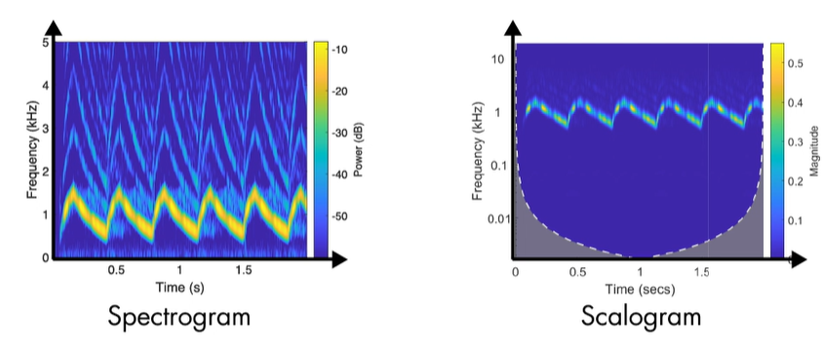

At a high level, both plots are created using the same process. First, we slice the time domain signal into smaller blocks. Then the power spectrum is calculated for each block. Now, the trick here is to use color to represent the magnitude of the power spectrum. Once that's done, you can simply plot your colorful data on a Frequency vs. Time plot

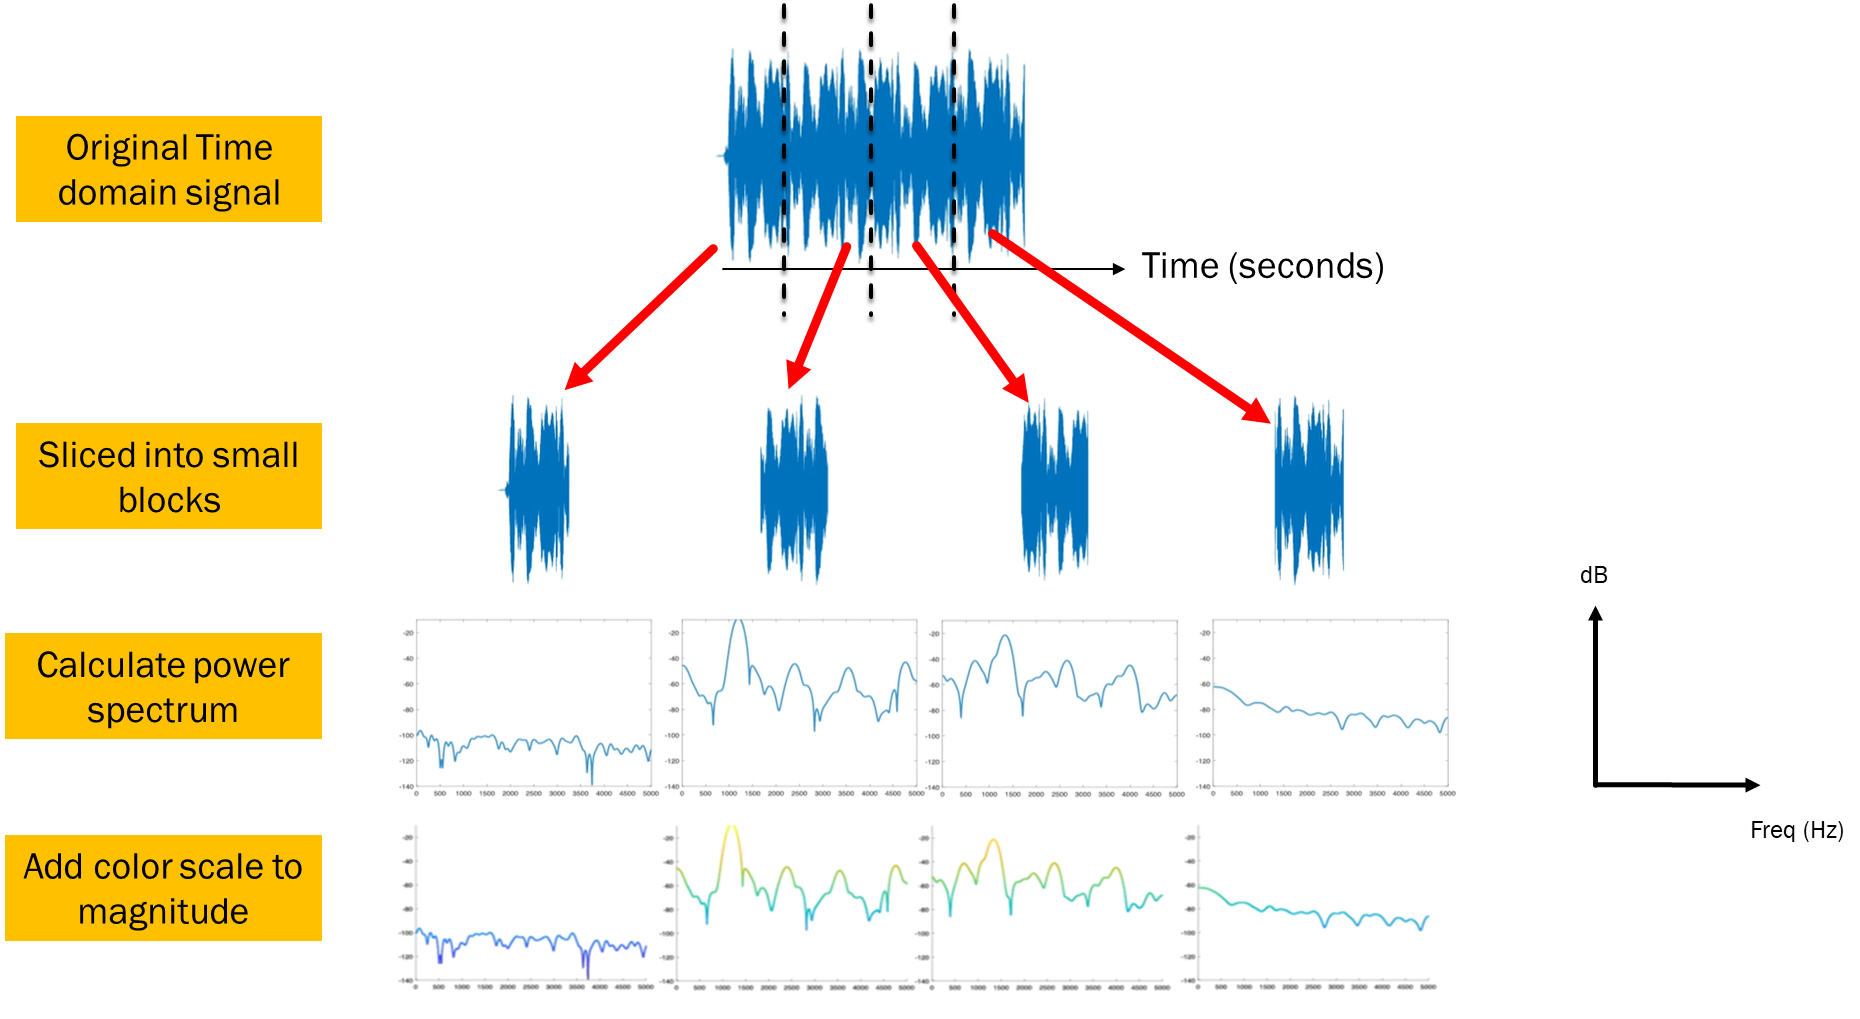

Then, rotate the colorized powerspectrum plot by 90 degree so that Frequency is now the y-axis. 

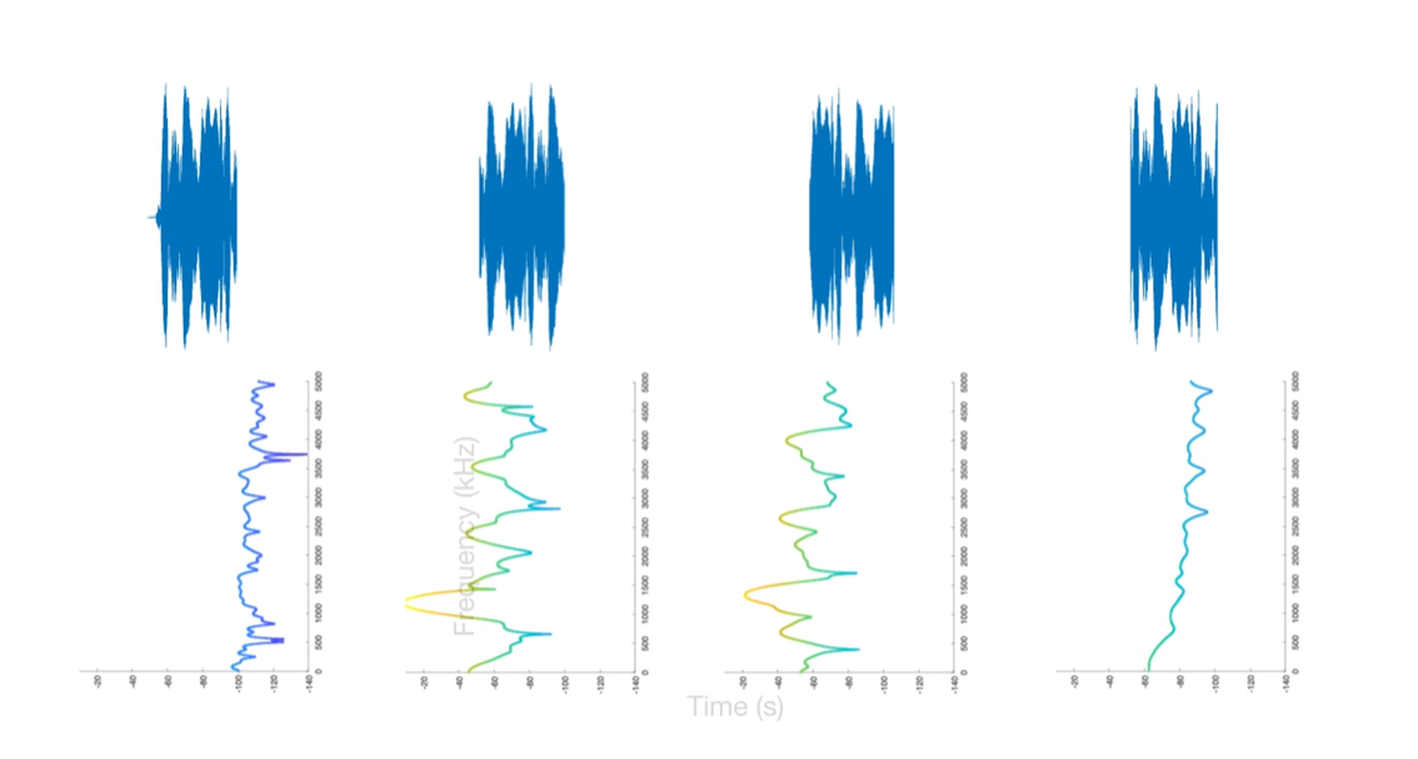

Since each block represents a different time instance, we can associate time data to our x-axis:

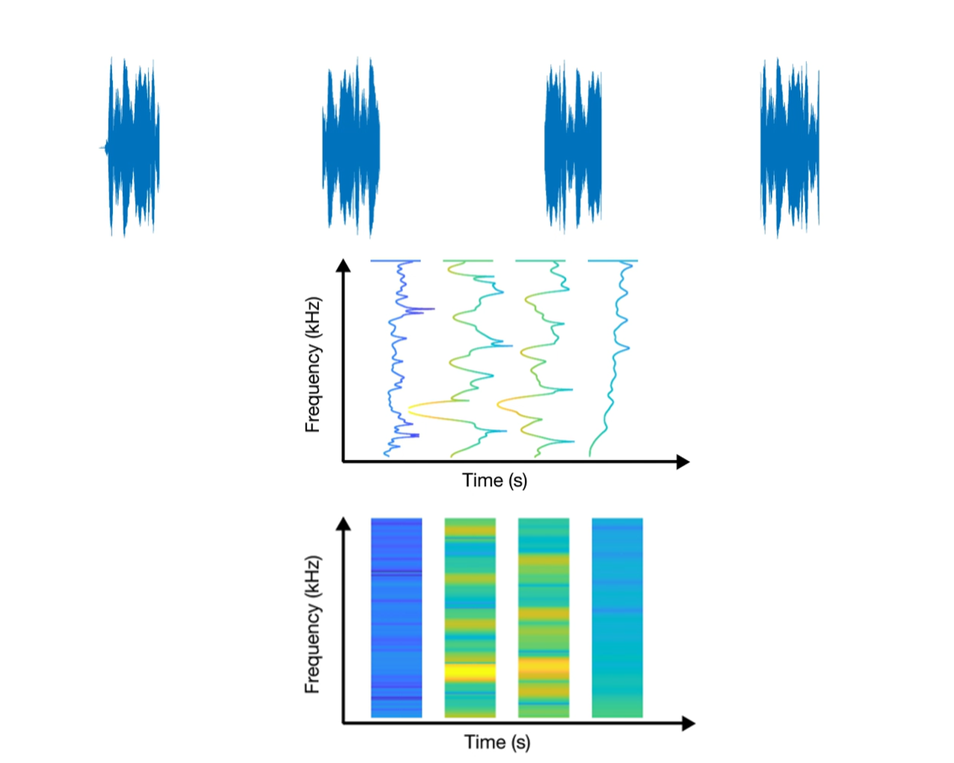

So should we use a spectogram or a scalogram? It depends. If your signal is best modeled using sine or cosine wave, then use spectogram. If it is better modeled using a wavelet or pulses, then use a scalogram. If you are not sure what to use, just try both and see which one gives better visualization. 

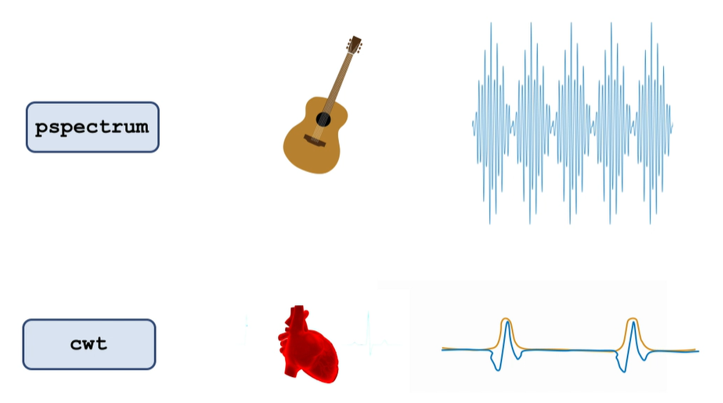

You can create a spectrogram with the `pspectrum` function by including the input `"spectrogram"`.

You can only create the spectrogram of one signal at a time, but the `quakes` table contains three signals. You can use dot-indexing to provide the signal and the time vectors separately.

`    pspectrum``(``data.Signal``,``data.Time``,``"spectrogram"``)`

**TASK**

Create a spectrogram of the Mount Wrangell signal in `quakes`.

You can see high-frequency bands in the spectrogram. The timestamps of these bands correspond with the local earthquakes near the Mount Wrangell seismic station.

Most tremors from local earthquakes contain frequencies between 2 Hz and 10 Hz. These bands will become more evident if you zoom in on that frequency range.

When you create the spectrogram, you can specify a frequency range with the `"FrequencyLimits"` option. 

    `pspectrum``(``data``,``"spectrogram"``,` `...`

        `"FrequencyLimits"``,``[``a` `b``])`

`Recreate the spectrogram using a frequency limit between 2 and 10 Hz`

Now the yellow bands are  more clearly prominent at these frequencies. However, there's still a lot of background noise. Notice that the colorbar goes from dark blue to yellow, but no dark blue is visible on the spectrogram.

You can remove frequencies that have low power using the `"MinThreshold"` option.

`pspectrum``(``data``,``"spectrogram"``,` `...`

    `"MinThreshold"``,``n``)` 

The background of the spectrogram has a lot of green, so you'll use the green colorbar value to choose the threshold (say at -50).

Now the spectrogram contains more details, but the area around the bands is still quite noisy. 

There are more options you can set while creating spectrograms, but you can also try different time-frequency visualization methods.

You can create scalograms with the `cwt` function.

`    cwt``(``sig``,``fs``)`

The first input is the signal, and the second input is the sample rate. 

You can also set the frequency limits with the `cwt` function.

`    cwt``(``sig``,``fs``,` `...`

        `"FrequencyLimits"``,``[``a` `b``])`

**TASK**

Create a scalogram of the Mount Wrangell signal. Recall that the sample rate is `1``/``0.02`.

Set the frequencies limits from 2 Hz to 10 Hz.

There isn't a `MinThreshold` option for the `cwt` function, but you can have the same effect by setting the colormap limits.

`    caxis``([``a` `b``])`

Notice that the scalogram colorbar shows the magnitude, not the power. You'll use a limit in the blue range (say, from 0 to 2) since the other colors are not very visible on the plot. 

## Lowpass filter

Filtering the Mount Wrangell Signal

The low frequencies and the high frequencies correspond to two different seismic events. You will extract the low frequency surface waves from the Indonesian earthquake. Then you'll extract the seismic activity that it caused in Alaska.

The HARP and PAX seismic stations recorded low-frequency surface waves from the Sumatra earthquake.

Although not obvious from the time domain, you've seen convincing evidence that the Mount Wrangell seismic station also recorded the same surface waves:

- Cross-correlation between the signals

- Power spectra show a similar peak around 0.05 Hz

In this activity, you'll filter the Mount Wrangell signal to view the low frequencies in the time domain.

To choose the passband frequency for filtering, it can help to add a vertical line at a given frequency to visualize using `xline` command. 

`    xline``(``pass``)`

Regenerate the semilog power spectrum that you created earlier and then add the x-line at frequency 0.1 Hz

%Replot semilog power spectrum

semilogx(f,db(p,"power"))
legend("HARP","PAX","WANC")
xlabel("Frequency (Hz)")
ylabel("Power Spectrum (dB)")


Add the x-line to the plot at frequency 0.1 Hz

When you lowpass filter the Mount Wrangell signal at `0.1` Hz, you'll primarily keep only the frequencies to the left of the vertical line.

You can lowpass filter with the `lowpass` function.

`    lowpass``(``tbl``,``pass``)`

You only need to filter the Mount Wrangell signal, which is stored in the `WANC` variable in `quakes`. To filter one variable in a timetable, you can use the colon (`:`) operator to get all timestamps for a given variable name

`    tbl``(``:,``"``VarName``"``)`

`and then apply lowpass to it`

`    lowpass(``tbl``(:,"``VarName``"),pass)`

**TASK**

Lowpass filter the `WANC` variable in `quakes` at `0.1` Hz. 

This will output 2 plots, belonging to the time domain and the frequency domain for the Mount Wrangell signal with the Filtered and Original version of the signal overlayed on top of each other. 

Notice that there are still frequencies over `0.1` in the Filtered version, but filtering removed some of the high frequencies.

Next, let's save the filtered signal to a variable so you can compare the filtered signal with the HARP and PAX signals.

Repeat the previous lowpass command, but this time, assign  it to the output variable named `lowWANC`.

`lowWANC` is a timetable with one variable named `WANC`. Since the time vector for `lowWANC` is still the same as `quakes`,  you can add `lowWANC` as a new variable in the `quakes` timetable.

To add a new variable to a table, you can use dot-notation.

`    tbl.NewVar` `=` `data`

**TASK**

Add `lowWANC.WANC` to the `quakes` table. Name the new variable `FiltWANC`.

**TASK**

Create a new figure using the `figure` command. Then create a stacked plot of all the signals in `quakes`.

The `FiltWANC` plot looks somewhat similar to HARP and PAX, but many of the curves are jagged. The jagged curves contain high-frequency content that was leftover from filtering.

To reduce the amount of high-frequency content in the filtered signal, you can increase the [steepness ](http://https//www.mathworks.com/help/signal/ref/lowpass.html#mw_3aa14271-5d7b-4a2a-8b29-b1f47d3ce414)in filter function. 

`    sig` `=` `lowpass``(``tbl``,``pass``,``"Steepness"``,``s``)`

**TASK**

Update the `lowpass` code. Set the `"Steepness"` option to 0.95. And repeat the subsequent steps.

## **Bandpass Filter**

Let's replot our Power spectrum again.

% Power spectrum replot
[p,f] = pspectrum(quakes);
figure
semilogx(f,db(p,"power"))
legend("HARP","PAX","WANC","Lowpass WANC","Location","best")
xlabel("Frequency (Hz)")
ylabel("Power Spectrum (dB)")

In the previous activity, you have extracted the low frequencies, which corresponded to the surface waves from the earthquake in Sumatra.

Now you need to get the high frequency content, which corresponds to the local earthquakes near Mount Wrangell. The frequency range of local earthquakes is 2 Hz to 10 Hz.

To extract these frequencies, you can use a bandpass filter to keep only the frequencies in that range.

`    bandpass``(``tbl``,``[``f1` `f1``])`

**TASK**

Bandpass filter the `WANC` variable in `quakes` from `2` to `10` Hz.

Repeat the task as above, but now assign it to an output variable named `bandWANC`

To plot the lowpass and the bandpass filtered signal, you can combine them in one timetable.

`    tbl` `=` `timetable``(``t``,``sig1``,``sig2``,``...`

`        'VariableNames'``,``[``"A"` `"B"``])`

**TASK**

Create a new timetable named `compfilt`. Use these inputs:

- The time vector from `quakes` or `bandWANC`

- `bandWANC.WANC`

- `quakes.FiltWANC`

- Set the variable names to `"Bandpass"` and `"Lowpass", respectively`

**TASK**

Create a new figure by entering `figure`. Then create a stacked plot of `compfilt`.

Set the x-limits from `2900` seconds to 3100 seconds to zoom in on two of the local earthquakes.

The earth scientists thought that the earthquake in Sumatra triggered the earthquakes in Alaska. Using filtering, they were able to compare the low frequency and high frequency signals from the Mount Wrangell seismometer. This provided a rare opportunity for them to confirm the relationship between two distant earthquakes.

If you scroll through the plot, you can see that each high frequency pulse occurs near a peak in the low frequency waves.

## Find Peaks

We have previously seen the spectrogram of the Mount Wrangell signal. The earthquakes occured wherever there's a band of frequencies from 2 Hz to 10 Hz. Can you use this spectrogram to find the timestamps of the earthquakes?

% Replot the spectogram
pspectrum(quakes.WANC,quakes.Time,"spectrogram","FrequencyLimits",[2 10],"MinThreshold",-50);

To compute anything from the spectrogram, first you need to get the arrays (instead of just the image).

`    [``p``,``f``,``t``]` `=` `pspectrum``(``sig``,``time``,``"spectrogram"``)`

The three outputs are the spectral estimates, the frequencies, and the time instants of each segment.

Compute [p, f , t] parameters for Mount Wrangell signal.

To find which timestamps contain lots of high frequencies, you could sum the power across all frequencies for each timestamp.

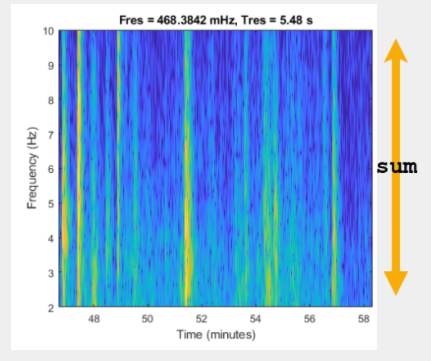

**TASK**

Calculate the `sum` of `p`. Name the output `psum`. Then create a plot of `psum` versus `t`.

You can see a few peaks in `psum`, but some peaks are much less promiment than others. To accentuate the peaks, you can calculate the power.

`    db(p,"power")`

**TASK**

Calculate the power of `psum` and name it `pwr`. Then create a plot of `pwr` versus `t`.

To find the timestamps of each earthquake, you can find the location of these spikes. The Find Local Extrema task located inside LIVE EDITOR/CODE section lets you interactively find local maxima in data.

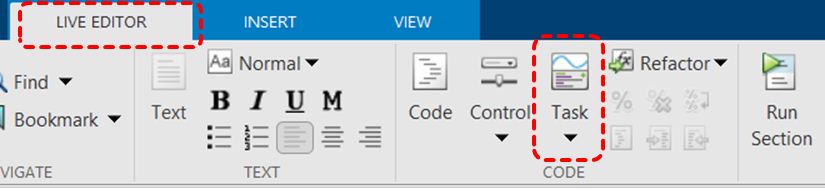

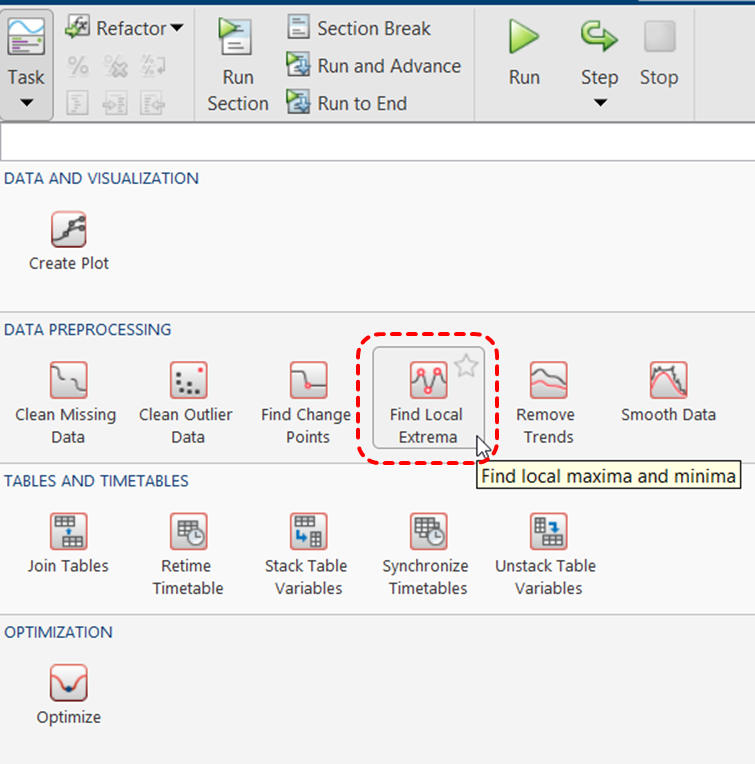

**TASK**

- Add the Find Local Extrema live task to the script

- Select `pwr` as the input data

- Name the output variable `findquakes. The option` is located in the `[``ChangeYourVariableNameHere``] = Local maxima in ``pwr``. `

- Select `t` as the x-axis data

% Find local maxima
findquakes = islocalmax(pwr,"MinProminence",10,"SamplePoints",t);

% Display results
clf
plot(t,pwr,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(t(findquakes),pwr(findquakes),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(findquakes))
hold off
legend
xlabel("t")


The default options find too many local extrema. You can modify the options to find just the earthquakes.

If you already knew how many earthquakes to find, you could enter that value for the maximum number of extrema. In most cases, you won't know the number of extrema already, so instead, you can tweak the prominence and separation options.

The prominence of a peak is a measure of its height and location relative to other peaks.

**TASK**

Increase the Min. prominence option to `10`.

Lastly, we can visualize the earthquakes that you just identified on the filtered signal by uncommenting the codes below

% plot(compfilt.Time,compfilt.Bandpass)
% hold on
% plot(t(findquakes),compfilt.Bandpass(findquakes),"ro")
% hold off
% title("Bandpass Signal")

And that's the end of this Signal Processing Lab. We hope that this lab excercise gives you some idea on how to go about exploring your own hypothesis and processing your own signal!